clc,clear,close all

global U
global num
global Num
global Umod
global hstep
global M2
global Upm
global Center
global Element
global M
global m_Hflux
global Umod

num = 160;  % 区间数量
Num = num+2;    % 周期边界条件，左右各加一个区间后，区间数量
left = -1;
right = 1;
time = 0.5/pi;
delta_t = 0.1*(right-left)/num;

hstep = (right-left)/num;   % 每个区间的长度，这里设置成等长。
Element_l = left-hstep:hstep:right; % 每个区间的左边界，大小为 1xNum
Element_r = left:hstep:right+hstep; % 每个区间的右边界，大小为 1xNum
Element = [Element_l',Element_r'];  % 每个区间的左右边界，大小为 Numx2
Center = mean(Element,2);           % 每个区间的中心点，大小为 Numx1

U = zeros(Num,3);       % 每个区间上的三个自由度
Umod = zeros(Num,2);
Upm = zeros(Num,2);

U0 = zeros(Num,3);
U1 = zeros(Num,3);
U2 = zeros(Num,3);
Un = zeros(Num,3);

M2 = 9;
m_Hflux = zeros(Num,1);   % num 个区间中间的 num+1 个间隔点上的数值通量。其中第一个位置只储存0。
M  = zeros(1,Num);

DGfun

## MainSolver

### 初始化

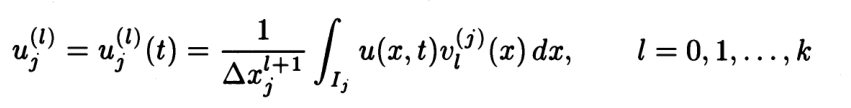

w0 = 0.555555555555556;
w1 = 0.888888888888889;
w2 = 0.555555555555556;
for i = 2:num+1
    x0 = -0.774596669241483 * 0.5 * hstep + Center(i);
    x1 = Center(i);
    x2 = 0.774596669241483 * 0.5 * hstep + Center(i);

    int1 = 0.5 * hstep * (w0 * u0(x0) * basefun0(i,x0) + w1 * u0(x1) * basefun0(i,x0) + w2 * u0(x2)) * basefun0(i,x0);
    U(i,1) = int1 / hstep;

    int2 = 0.5 * hstep * (w0 * u0(x0) * basefun1(i,x0) + w1 * u0(x1) * basefun1(i,x1) + w2 * u0(x2) * basefun1(i,x2));
    U(i,2) = int2 / hstep^2;

    int3 = 0.5 * hstep * (w0 * u0(x0) * basefun2(i,x0) + w1 * u0(x1) * basefun2(i,x1) + w2 * u0(x2) * basefun2(i,x2));
    U(i,3) = int3 / hstep^3;
end

龙格库塔迭代

for now = delta_t:delta_t:time

    RungeKutta0();

    U0=U;
    Solvestep();

    RungeKutta1();

    for i = 2:num+1
        U1(i,1) = U0(i,1) + delta_t * Lh0(i);
        U1(i,2) = U0(i,2) + delta_t * Lh1(i);
        U1(i,3) = U0(i,3) + delta_t * Lh2(i);
    end
    U=U1;
    Solvestep();

    RungeKutta2();

    for i = 2:num+1
        U2(i,1) = 0.75 * U0(i,1) + 0.25 * U1(i,1) + 0.25 * delta_t * Lh0(i);
        U2(i,2) = 0.75 * U0(i,2) + 0.25 * U1(i,2) + 0.25 * delta_t * Lh1(i);
        U2(i,3) = 0.75 * U0(i,3) + 0.25 * U1(i,3) + 0.25 * delta_t * Lh2(i);
    end
    U=U2;
    Solvestep();

    RungeKutta3();

    for i = 2:num+1
        Un(i,1) = 1/3 * U0(i,1) + 2/3 * U2(i,1) + 2.0/3.0 * delta_t * Lh0(i);
        Un(i,2) = 1/3 * U0(i,2) + 2/3 * U2(i,2) + 2.0/3.0 * delta_t * Lh1(i);
        Un(i,3) = 1/3 * U0(i,3) + 2/3 * U2(i,3) + 2.0/3.0 * delta_t * Lh2(i);
    end
    U=Un;
    SetBoundary();
    GetUmod();
    GetM();
    UseLimiter();
    UpdateVariables();
end

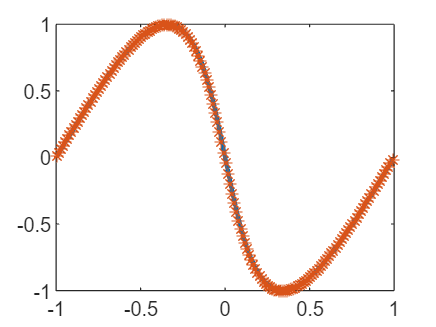

for i = 2:num+1
    x(i-1) = Center(i);
    y(i-1) = u(i,Center(i));
end
plot(x,y,'LineWidth',2)
hold on

xx = x;
yy = zeros(1,length(xx));
syms xi
for i = 1:length(xx)
    x = xx(i);
    xii = vpasolve(xi-x+u0(xi)*time);
    yy(i) = u0(xii);
end
plot(xx,yy,'*')
hold off


err1 = abs(y-yy)

err1 =     0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0003    0.0003    0.0003    0.0003    0.0002    0.0002    0.0001    0.0001


norm(err1,1)

ans = 0.0706

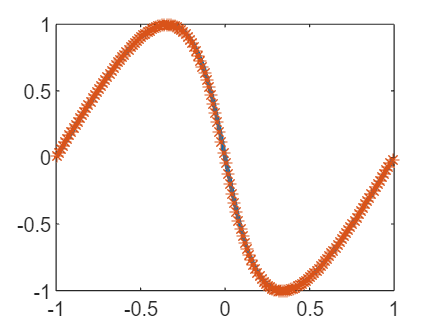

xy = readmatrix("真-scalar DG result.txt");
x = xy(:,1);
y = xy(:,2);
plot(x,y,'LineWidth',2)
hold on

xx = x;
yy = zeros(1,length(xx));
syms xi
for i = 1:length(xx)
    x = xx(i);
    xii = vpasolve(xi-x+u0(xi)*time);
    yy(i) = u0(xii);
end
plot(xx,yy,'*')
hold off


err2 = abs(y'-yy)

err2 =     0.0000    0.0001    0.0001    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0005    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0009    0.0009    0.0009    0.0009    0.0009    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0009    0.0009    0.0009    0.0009    0.0008    0.0008    0.0008    0.0007    0.0007    0.0006    0.0005    0.0005    0.0004    0.0003


norm(err2,1)

ans = 0.1352